clc;
clear;
close all;

load('modelo_lin.mat')

load("UncertainLinmodel.mat")

latmod

latmod =
 
  A = 
                 v           p
   v        -0.875      0.8751
   p        -2.831      -16.14
   r         1.706      0.5154
   phi           0           1
   psi           0           0
 
                 r         phi
   v        -16.82       9.791
   p         3.377           0
   r        -2.783           0
   phi     0.05385  -1.455e-24
   psi       1.001  -2.706e-23
 
               psi
   v             0
   p             0
   r             0
   phi           0
   psi           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p
   beta  0.05882        0
   p           0        1
   r           0        0
   phi         0        0
   psi         0        0
 
               r      phi
   beta        0        0
   p           0        0
   r           1        0
   phi         0        1
   psi         0        0
 
        

linmodel

linmodel =
 
  A = 
                 phi
   phi    -1.455e-24
   theta  -3.665e-24
   psi    -2.706e-23
   p               0
   q               0
   r               0
   u               0
   v           9.791
   w         0.01685
   Xe         0.9141
   Ye      8.457e-05
   Ze       0.001571
   omega           0
 
               theta
   phi     3.676e-24
   theta           0
   psi     1.976e-25
   p               0
   q               0
   r               0
   u          -9.791
   v       0.0009072
   w         -0.5272
   Xe     -5.589e-17
   Ye     -5.146e-12
   Ze            -17
   omega           0
 
                 psi
   phi             0
   theta           0
   psi             0
   p               0
   q               0
   r               0
   u               0
   v               0
   w               0
   Xe            -17
   Ye      -0.001573
   Ze              0
   omega           0
 
                   p
   phi             1
   theta           0
   psi             0
   p    

longmod

longmod =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q      -8.001e-16
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711    

USSlinmodel

USSlinmodel =

  Uncertain continuous-time state-space model with 14 outputs, 8 inputs, 13 states.
  The model uncertainty consists of the following blocks:
    A101: Uncertain real, nominal = 0.914, variability = [-10,10]%, 1 occurrences
    A102: Uncertain real, nominal = -5.59e-17, variability = [-10,10]%, 1 occurrences
    A103: Uncertain real, nominal = -17, variability = [-10,10]%, 1 occurrences
    A108: Uncertain real, nominal = -1, variability = [-10,10]%, 1 occurrences
    A109: Uncertain real, nominal = -0.00172, variability = [-10,10]%, 1 occurrences
    A11: Uncertain real, nominal = -1.46e-24, variability = [-10,10]%, 1 occurrences
    A111: Uncertain real, nominal = 8.46e-05, variability = [-10,10]%, 1 occurrences
    A112: Uncertain real, nominal = -5.15e-12, variability = [-10,10]%, 1 occurrences
    A113: Uncertain real, nominal = -0.00157, variability = [-10,10]%, 1 occurrences
    A117: Uncertain real, nominal = 0.999, variability = [-10,10]%, 1 occurrences
    A118

uvars

uvars = struct with fields:
     A101: [1×1 ureal]
     A102: [1×1 ureal]
     A103: [1×1 ureal]
     A108: [1×1 ureal]
     A109: [1×1 ureal]
      A11: [1×1 ureal]
     A111: [1×1 ureal]
     A112: [1×1 ureal]
     A113: [1×1 ureal]
     A117: [1×1 ureal]
     A118: [1×1 ureal]
     A119: [1×1 ureal]
      A12: [1×1 ureal]
     A121: [1×1 ureal]
     A122: [1×1 ureal]
     A127: [1×1 ureal]
     A128: [1×1 ureal]
     A129: [1×1 ureal]
    A1310: [1×1 ureal]
    A1311: [1×1 ureal]
    A1312: [1×1 ureal]
    A1313: [1×1 ureal]
     A137: [1×1 ureal]
     A138: [1×1 ureal]
     A139: [1×1 ureal]
      A14: [1×1 ureal]
      A15: [1×1 ureal]
      A16: [1×1 ureal]
      A21: [1×1 ureal]
      A25: [1×1 ureal]
      A26: [1×1 ureal]
      A31: [1×1 ureal]
      A32: [1×1 ureal]
      A35: [1×1 ureal]
      A36: [1×1 ureal]
     A410: [1×1 ureal]
     A411: [1×1 ureal]
     A412: [1×1 ureal]
     A413: [1×1 ureal]
      A44: [1×1 ureal]
      A45: [1×1 ureal]
      A46: [1×1 ureal]
      


%USSlinmodel = createUSSmodel(linmodel,10)
%uvars = ufind(USSlinmodel)

# Tarea1:

## Modelo Longitudinal:

%Carga del modelo
Alongmod = longmod.A;
Blongmod = longmod.B;
Clongmod = longmod.C;
Dlongmod = longmod.D;
longmod

longmod =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q      -8.001e-16
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711    



%eliminacion de datos irrelevantes
Alongmod(abs(Alongmod)<1e-10)=0;
Blongmod(abs(Blongmod)<1e-10)=0;
Clongmod(abs(Clongmod)<1e-10)=0;
Dlongmod(abs(Dlongmod)<1e-10)=0;

longmodNames = longmod.StateName;
Blongmod=Blongmod(:,1);
Clongmod=Clongmod(4,:);
Dlongmod=Dlongmod(4,1);

G=ss(Alongmod,Blongmod,Clongmod,Dlongmod);
G.StateName=longmod.StateName

G =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q               0
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
              u1
   u      0.4681
   w      -2.711
   q      -134.1
   theta       0
 

G.InputName = 'elevador';
G.OutputName = 'theta';
G

G =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q               0
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
          elevador
   u        0.4681
   w        -2.711
   q        -134.1
   theta  

longmod

longmod =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q      -8.001e-16
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711    

s=tf('s');

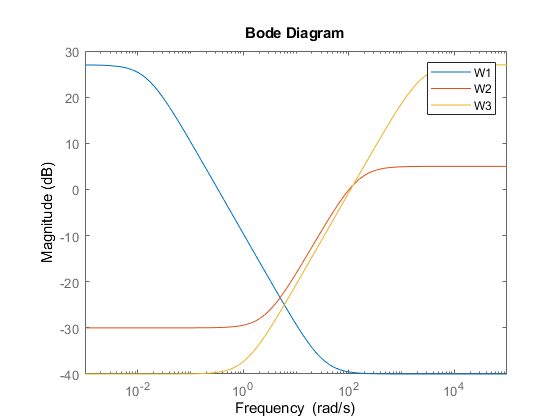

W1 = makeweight(db2mag(27),[6 db2mag(-25)],db2mag(-40)); %filtro pasa bajos
W2 = makeweight(db2mag(-30),[8 db2mag(-20)],db2mag(5)); 
W3 = makeweight(db2mag(-40),[6 db2mag(-25)],db2mag(27)); %filtro pasa altos

bodemag(W1,W2,W3)
legend

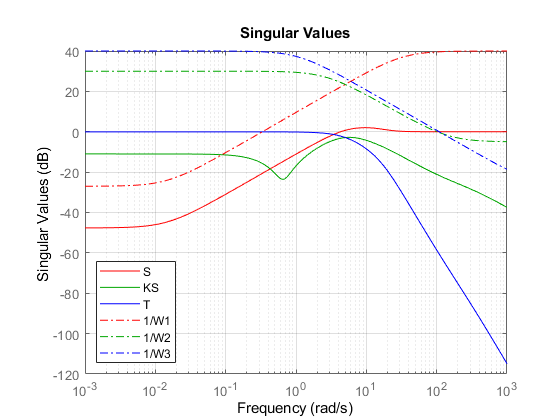


[K_Long,CL,gamma] = mixsyn(G,W1,W2,W3);
S = feedback(1,G*K_Long);
KS = K_Long*S;
T = 1-S;
sigma(S,'r',KS,'g',T,'b',1/W1,'r-.',ss(1/W2),'g-.',1/W3,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid

W1

[K_Long,CL,gamma]=mixsyn(G,W1,[],[]);
OL=series(K_Long,G);
GCL1=feedback(OL,1);
figure()
%hold on
%step(GCL1,"r")

W2

[K_Long,CL,gamma]=mixsyn(G,[],W2,[]);
OL=series(K_Long,G);
GCL2=feedback(OL,1);

%step(GCL2,"g")

W3

[K_Long,CL,gamma]=mixsyn(G,[],[],W3);
OL=series(K_Long,G);
GCL3=feedback(OL,1);
%step(GCL3,"b:")


ALL W

[K_Long,CL,gamma]=mixsyn(G,W1,W2,W3);
OL=series(K_Long,G);
GCL=feedback(OL,1);
step(GCL,"k--")


Ajustes

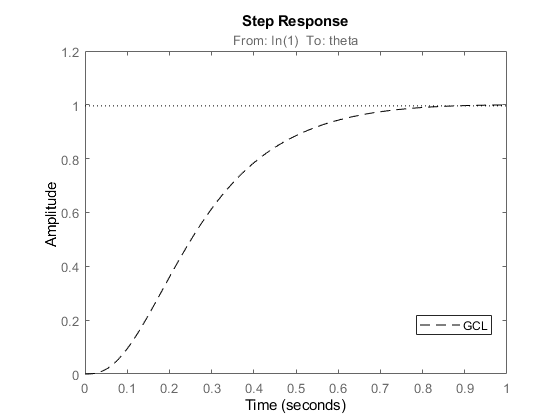

axis([0 1 0 1.2])
legend("Location","best")
hold off

format long
STINFOact=stepinfo(GCL)

STINFOact = struct with fields:
        RiseTime: 0.412239256698317
    SettlingTime: 0.708577593816425
     SettlingMin: 0.897277316055928
     SettlingMax: 1.000012110349417
       Overshoot: 0.396274302508703
      Undershoot: 0
            Peak: 1.000012110349417
        PeakTime: 1.070497209309953


STINFOprev=STINFOact;
%STINFOprev.Overshoot-STINFOact.Overshoot
%STINFOprev.Undershoot-STINFOact.Undershoot
%STINFOprev.RiseTime-STINFOact.RiseTime
DELTAPEAK=STINFOact.Peak-STINFOprev.Peak

DELTAPEAK =      0


DELTAPEAKTIME=STINFOact.PeakTime-STINFOprev.PeakTime

DELTAPEAKTIME =      0


%STINFOprev.SettlingMin-STINFOact.SettlingMin
%STINFOprev.SettlingMax-STINFOact.SettlingMax
DELTASETTIME=STINFOact.SettlingTime-STINFOprev.SettlingTime

DELTASETTIME =      0




STINFOprev=STINFOact;


function [USSmodel] = createUSSmodel(linmodel,Delta)
% Create a new SS model with 5% uncertainty for each element of A,B,C and D

% Get the dimensions of A,B,C and D
[n,m] = size(linmodel.B);
[p,n] = size(linmodel.C);

% Create a ureal object with 5% uncertainty

% Iterate over each element of A,B,C and D and add uncertainty
for i=1:n
    for j=1:n
        if linmodel.A(i,j)~=0
            A(i,j) = ureal(['A' num2str(i) num2str(j)],linmodel.A(i,j),'Percentage',Delta);
            else
            A(i,j)=0;
        end
    end
    for j=1:m
        if linmodel.B(i,j)~=0
            B(i,j) = ureal(['B' num2str(i) num2str(j)],linmodel.B(i,j),'Percentage',Delta);
            else
            B(i,j)=0;
        end
    end
end

for i=1:p
    for j=1:n
        if linmodel.C(i,j)~=0
            C(i,j) = ureal(['C' num2str(i) num2str(j)],linmodel.C(i,j),'Percentage',Delta);
            else
            C(i,j)=0;
        end
    end
    for j=1:m
        if linmodel.D(i,j)~=0
            D(i,j) = ureal(['D' num2str(i) num2str(j)],linmodel.D(i,j),'Percentage',Delta);
        else
            D(i,j)=0;
        end
    end
end

% Create a USS model
USSmodel = uss(ss(A,B,C,D));

end